# Compute fluxes

clc, clear
set_demo_defaults

We regularly compute fluxes of the gradients of scalar potential fields:


$$\mathbf{q} = K\nabla h$$


where $h$ is the scalar field. The discrete approximation can be computed with the discrete gradient as

`q = -``K``Gh `.

This works in the **interior** of the domain, but it fails on the boundary due to the natural (no flow) boundary conditions implemented in `G`. We can illustrate this with a simple example of uniform one dimensional flow as given by the following problem:

PDE: $-\nabla\cdot\left[K\nabla h\right]=f_s$  on $x\in\left[0,\,L\right]$

BC:    $h(0)=1$ and $h(L) = 0$

This problem has the simple analytic solution $h = 1-x$ and $q=K$.

ha = @(x) 1-x; qa = @(x,K) K + 0*x; xa = linspace(0,1,1e2);

The numerical solution is computed as follows

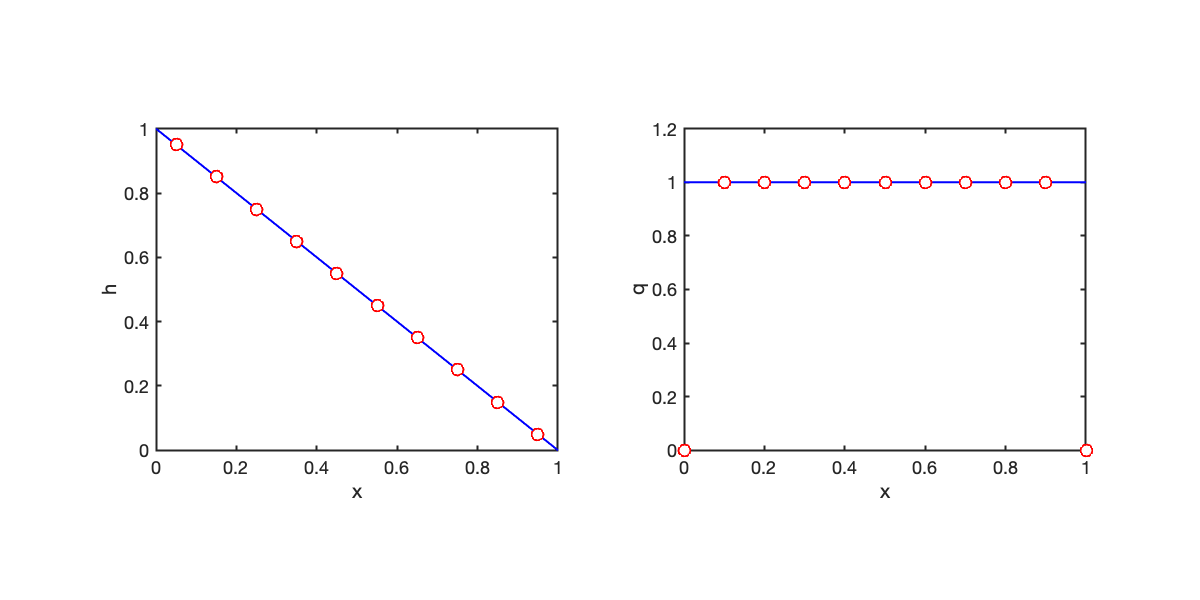

% Grid and operators
K = 1;
Grid.xmin = 0; Grid.xmax =1; Grid.Nx = 10;
Grid = build_grid(Grid);
[D,G,C,I,M] = build_ops(Grid);
L = -D*K*G;
fs = spalloc(Grid.N,1,0);

% Dirichlet BC's
BC.dof_dir = [Grid.dof_xmin;Grid.dof_xmax];
BC.g = ha(Grid.xc(BC.dof_dir));
[B,N,fn] = build_bnd(BC,Grid,I);

% Solve problem and compute flux
h = solve_lbvp(L,fs,B,BC.g,N);
q = -K*G*h;

% plot solution
figure('position',[10 10 1200 600])
subplot 121
plot(xa,ha(xa),'b-'), hold on
plot(Grid.xc,h,'ro','markersize',12,'markerfacecolor','w')
xlabel 'x', ylabel 'h'
pbaspect([1 .8 1])

subplot 122
plot(xa,qa(xa,K),'b-'), hold on
plot(Grid.xf,q,'ro','markersize',12,'markerfacecolor','w')
xlabel 'x', ylabel 'q'
pbaspect([1 .8 1])

The flux computation fails on the boundary, because the gradient is set to zero by `G`.

## Reconstruction of boundary fluxes

We use the discrete balance in the boundary cell to compute the unknown boundary flux exactly. Consider the discrete linear system

`Lh = fs`

with the discrete **residual** equation

`r = Lh - fs`

If the discrete equations are satisfied the residual vanishes, `r = 0`. This is true in the interior but not on the boundary because the boundary flux has been set to zero.

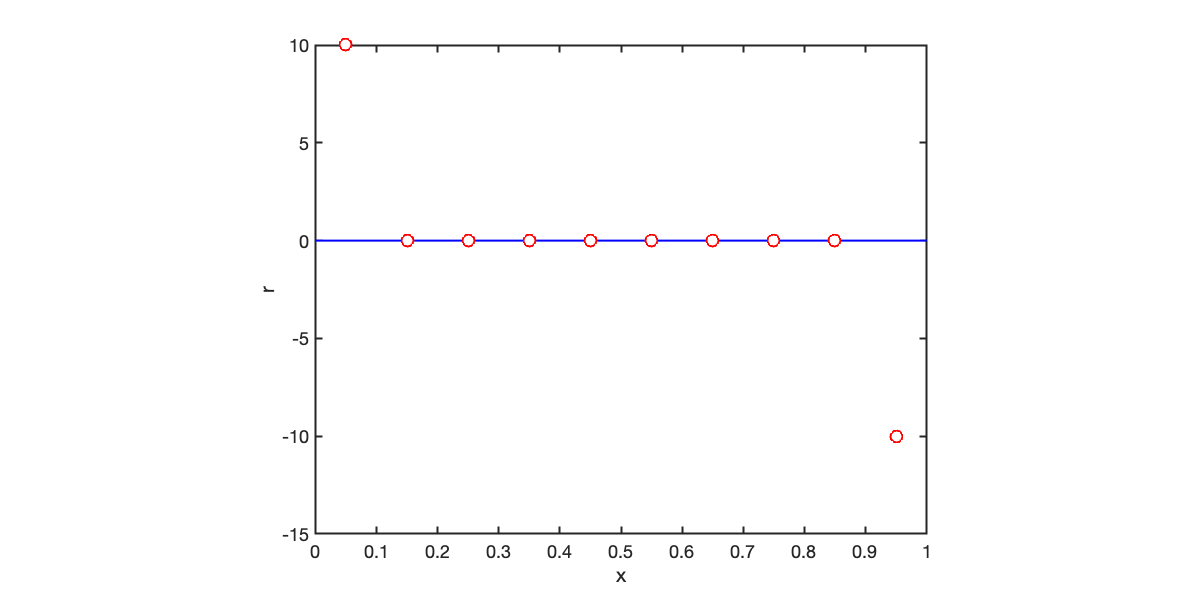

res = @(h) L*h-fs;
figure('position',[10 10 1200 600])
plot([0,1],[0 0],'b-'), hold on
plot(Grid.xc,res(h),'ro','markersize',12,'markerfacecolor','w')
xlabel 'x', ylabel 'r'
pbaspect([1 .8 1])

## Relation between **fn** and `r`

The non-zero residual in the boundary cells contains information about the unknown boundary flux. To see this consider the discrete system with a Neumann flux boundary

`Lh = fs + fn`

where fn is the addtional r.h.s. term due to the boundary fluxes. By definition of the residual, `r = Lh - fs`, we have thar

`r = fn`.

In other words the residual is equal to the r.h.s. due to fluxes!  In the center of the doamin `fn = 0`, but not on boundaries with prescribed fluxes. The entries of fn corresponding to boundary cells are given by


$$f_n = q_b\frac{A}{V}$$


where $q_b$ and $A$ are the prescribed flux on and area of the boundary face and $V$is the volume of the boundary cell. If we are given $f_n =r$ instead of qb we can reverse the argument and solve for the boundary flux

$q_b= r \frac{V}{A}$   (up to  sign!).

Note: We *assume* that each boundary cell has only one face with a boundary flux. In higher dimensions cells along edges or corners can have multiple faces with boundary fluxes. In that case the residual has to be distributed onto multiple faces, but we will not discuss this here.

r = res(h);
q(1) = r(1)*Grid.V(1)/Grid.A(1);
q(Grid.Nf) = r(Grid.N)*Grid.V(Grid.N)/Grid.A(Grid.N);
q(1) 

ans = 1

q(Grid.Nf)

ans = -1.0000

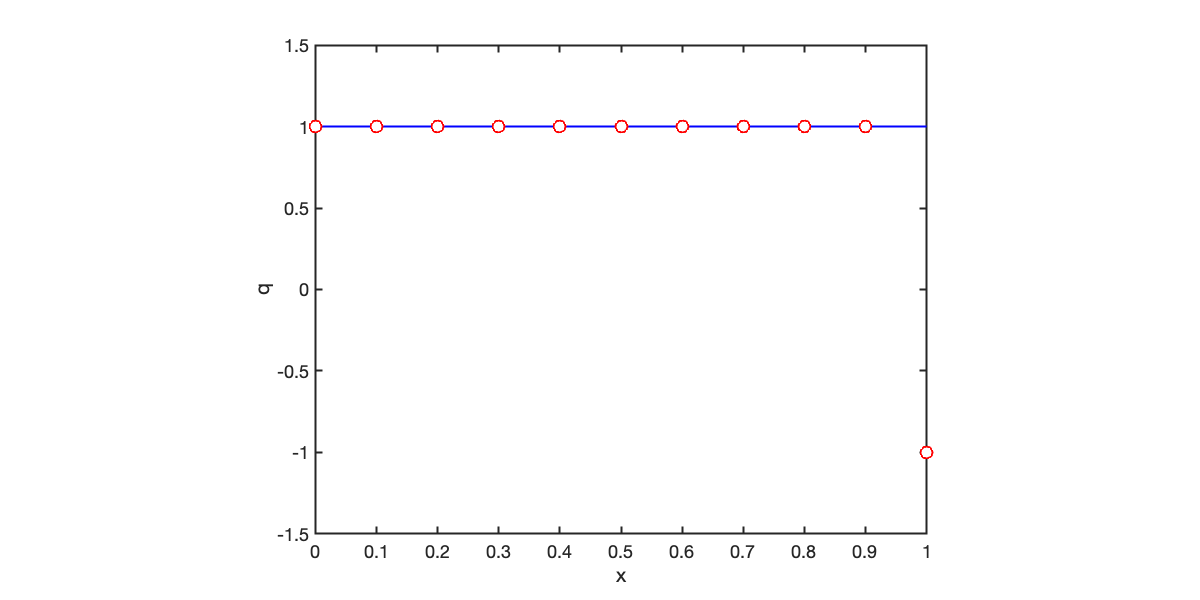

figure('position',[10 10 1200 600])
plot(xa,qa(xa,K),'b-'), hold on
plot(Grid.xf,q,'ro','markersize',12,'markerfacecolor','w')
xlabel 'x', ylabel 'q'
pbaspect([1 .8 1])

There is clearly a sign problem on the `xmax` side of the domain.

## Sign change on max-boundary

We want that the q reconstructed on the boundary has a sign so that it fits with the rest of the fluxes computed from Darcy's law: `q = -Kd*G*h`. In this vector fluxes in increasing x-direction are positive. In our reconstruction fluxes into the domain are positive. 

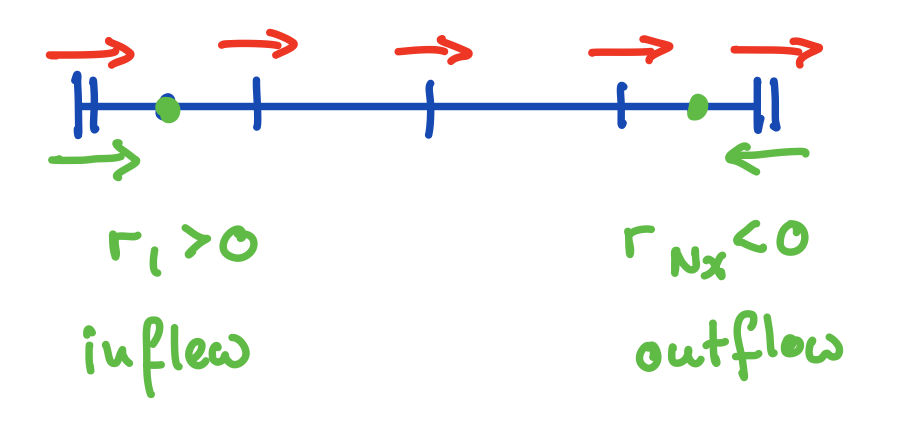

Therefore, we have to change the sign on the xmax boundary.

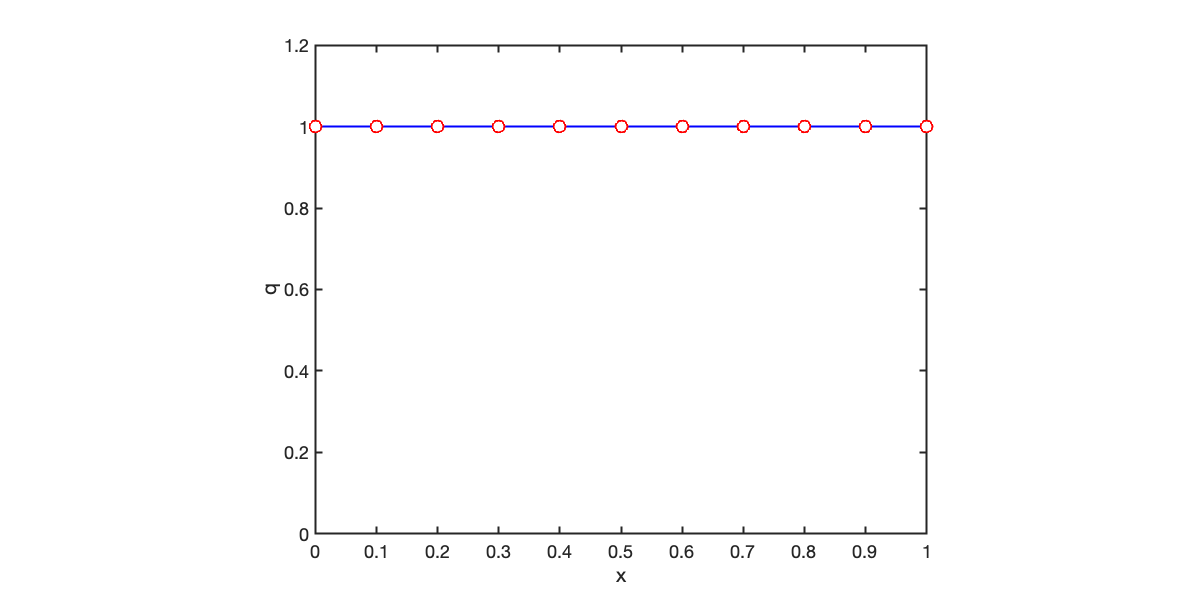

q(Grid.Nf) = - r(Grid.N)*Grid.V(Grid.N)/Grid.A(Grid.N);

figure('position',[10 10 1200 600])
plot(xa,qa(xa,K),'b-'), hold on
plot(Grid.xf,q,'ro','markersize',12,'markerfacecolor','w')
xlabel 'x', ylabel 'q', ylim([0 1.2])
pbaspect([1 .8 1])